% The given solar flux function
f_solar_flux = @(t) -361 * cos(pi * t/(12 * 3600)) + 224 * cos(pi * t/(6 * 3600)) + 210;
f_outside_air = @(t) -3 + 6*sin( (2*pi*t)/(24*3600) + 3*pi/4 );

k_fiberglass = 0.04 % W/m K
rho_thermal_mass = 3000; % kg/m^3
c_thermal_mass = 800; % J/kg K

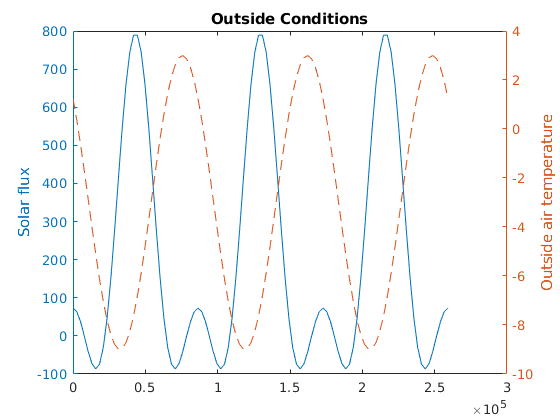

days = 3;
tspan = linspace(0, days*24*3600, 100);

figure()
yyaxis left
plot(tspan, f_solar_flux(tspan));
ylabel("Solar flux")

yyaxis right
plot(tspan, f_outside_air(tspan), '--');
ylabel("Outside air temperature")
title("Outside Conditions")